# Analysis of the Data from iPSC Reprogramming

clearvars
addpath(genpath('../'))

## Load the processed  data and normalize

load ipsc_early.mat
data = data_early';
true_labs = true_labs_early;
data = log(data+1);
[N_cell,N_genes] = size(data);

## Estimation of cluster number


out = EstClusterNum(data,[]);

Computed P-values 500 of 1081 datapoints...
Computed P-values 1000 of 1081 datapoints...
Mean value of sigma: 0.99264
Minimum value of sigma: 0.70989
Maximum value of sigma: 1.1764


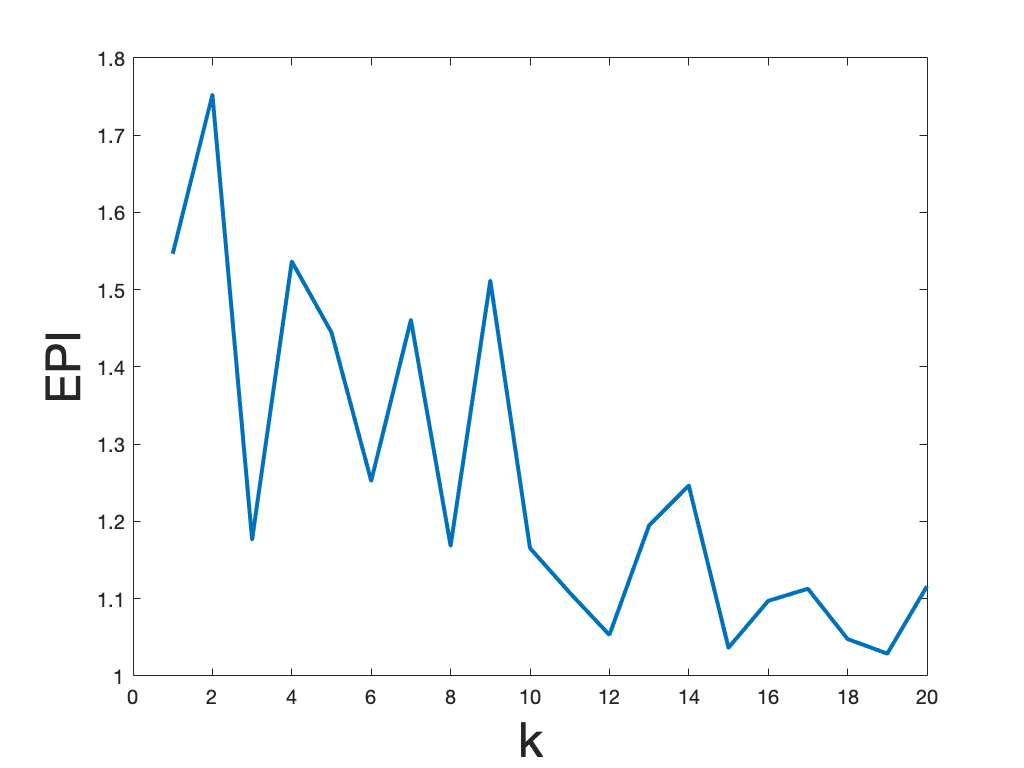

figure;
plot(out.ratio(1:20),'linewidth',2.0)
xlabel('k', 'FontSize', 24);
ylabel('EPI', 'FontSize', 24);

## Initial Visualization by tSNE

choice_distance = 'cosine';
Dist = squareform(pdist (data,choice_distance));
ydata = tsne_d(Dist);

Computed P-values 500 of 1081 datapoints...
Computed P-values 1000 of 1081 datapoints...
Mean value of sigma: 0.072516
Minimum value of sigma: 0.041545
Maximum value of sigma: 0.18809
Iteration 10: error is 45.6682
Iteration 20: error is 41.7475
Iteration 30: error is 41.1632
Iteration 40: error is 40.824
Iteration 50: error is 40.9121
Iteration 60: error is 40.7484
Iteration 70: error is 40.822
Iteration 80: error is 40.8243
Iteration 90: error is 40.6791
Iteration 100: error is 2.219
Iteration 110: error is 1.7502
Iteration 120: error is 1.495
Iteration 130: error is 1.3867
Iteration 140: error is 1.3403
Iteration 150: error is 1.3158
Iteration 160: error is 1.2988
Iteration 170: error is 1.286
Iteration 180: error is 1.2761
Iteration 190: error is 1.2682
Iteration 200: error is 1.2617
Iteration 210: error is 1.2563
Iteration 220: error is 1.2517
Iteration 230: error is 1.2476
Iteration 240: error is 1.2441
Iteration 250: error is 1.2411
Iteration 260: error is 1.236
Iteration 270: e

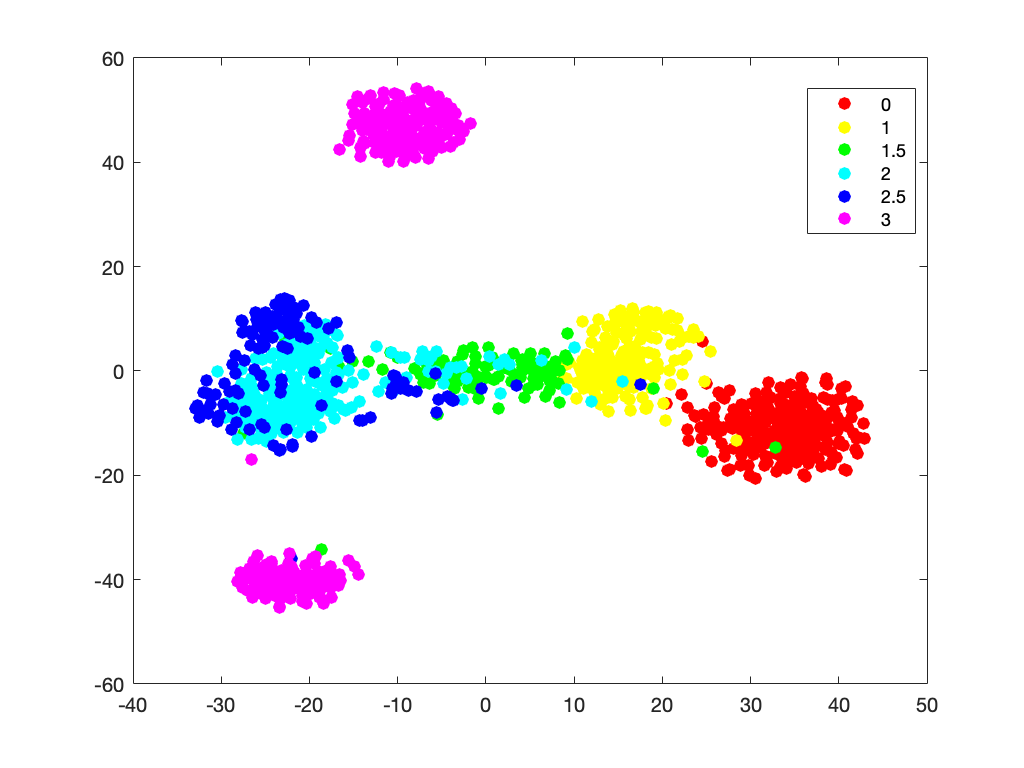

score = ydata;
figure;
gscatter(score(:,1),score(:,2),true_labs,[],[],22);

score_tsne = score;

## MuTrans Dynamical Analysis of the Single-Cell Data

parameter and option settings

rng(1)
par.choice_distance = 'cosine';
par.perplex = 200;
par.K_cluster = 9;
par.trials = 10;
par.true_labs = true_labs;
par.weight_scale = false;

% Dynamical Analysis and Output
tic;
Output = DynamicalAnalysis (data, par);

Computed P-values 500 of 1081 datapoints...
Computed P-values 1000 of 1081 datapoints...
Mean value of sigma: 0.14518
Minimum value of sigma: 0.12069
Maximum value of sigma: 0.18055
Computed P-values 500 of 1081 datapoints...
Computed P-values 1000 of 1081 datapoints...
Mean value of sigma: 0.072516
Minimum value of sigma: 0.041545
Maximum value of sigma: 0.18809
Iteration 10: error is 45.9866
Iteration 20: error is 42.0362
Iteration 30: error is 41.4032
Iteration 40: error is 41.0036
Iteration 50: error is 41.085
Iteration 60: error is 40.7333
Iteration 70: error is 40.9649
Iteration 80: error is 40.8853
Iteration 90: error is 40.9679
Iteration 100: error is 2.2247
Iteration 110: error is 1.7165
Iteration 120: error is 1.463
Iteration 130: error is 1.3884
Iteration 140: error is 1.3483
Iteration 150: error is 1.3232
Iteration 160: error is 1.3058
Iteration 170: error is 1.2926
Iteration 180: error is 1.2826
Iteration 190: error is 1.2745
Iteration 200: error is 1.268
Iteration 210: er

J_new = 3.6647

J_new = 3.6337

J_new = 3.6185

J_new = 3.5994

J_new = 3.5904

J_new = 3.5893

J_new = 3.5886

J_new = 3.5887

Computed P-values 500 of 1081 datapoints...
Computed P-values 1000 of 1081 datapoints...
Mean value of sigma: 0.072516
Minimum value of sigma: 0.041545
Maximum value of sigma: 0.18809
Iteration 10: error is 46.186
Iteration 20: error is 42.3246
Iteration 30: error is 41.4498
Iteration 40: error is 41.4262
Iteration 50: error is 41.3254
Iteration 60: error is 41.1351
Iteration 70: error is 41.1536
Iteration 80: error is 41.1458
Iteration 90: error is 41.0271
Iteration 100: error is 2.2581
Iteration 110: error is 1.7746
Iteration 120: error is 1.5276
Iteration 130: error is 1.4305
Iteration 140: error is 1.3806
Iteration 150: error is 1.3404
Iteration 160: error is 1.3065
Iteration 170: error is 1.2907
Iteration 180: error is 1.281
Iteration 190: error is 1.2729
Iteration 200: error is 1.2662
Iteration 210: error is 1.2606
Iteration 220: error is 1.2556
Iteration 230: error is 1.2514
Iteration 240: error is 1.2477
Iteration 250: error is 1.2444
Iteration 260: error is 1.239
Iteration 270

J_new = 3.6663

J_new = 3.6516

J_new = 3.6376

J_new = 3.6230

J_new = 3.6116

J_new = 3.5914

J_new = 3.5889

J_new = 3.5883

J_new = 3.5884

Computed P-values 500 of 1081 datapoints...
Computed P-values 1000 of 1081 datapoints...
Mean value of sigma: 0.072516
Minimum value of sigma: 0.041545
Maximum value of sigma: 0.18809
Iteration 10: error is 46.143
Iteration 20: error is 41.6887
Iteration 30: error is 41.198
Iteration 40: error is 41.0052
Iteration 50: error is 41.0617
Iteration 60: error is 41.0737
Iteration 70: error is 40.9408
Iteration 80: error is 40.956
Iteration 90: error is 40.9067
Iteration 100: error is 2.2402
Iteration 110: error is 1.7567
Iteration 120: error is 1.4781
Iteration 130: error is 1.3828
Iteration 140: error is 1.3371
Iteration 150: error is 1.3124
Iteration 160: error is 1.2952
Iteration 170: error is 1.2827
Iteration 180: error is 1.2732
Iteration 190: error is 1.2654
Iteration 200: error is 1.2592
Iteration 210: error is 1.254
Iteration 220: error is 1.2495
Iteration 230: error is 1.2456
Iteration 240: error is 1.2422
Iteration 250: error is 1.2392
Iteration 260: error is 1.2344
Iteration 270:

J_new = 3.6584

J_new = 3.6262

J_new = 3.6133

J_new = 3.5931

J_new = 3.5907

J_new = 3.5899

J_new = 3.5901

Computed P-values 500 of 1081 datapoints...
Computed P-values 1000 of 1081 datapoints...
Mean value of sigma: 0.072516
Minimum value of sigma: 0.041545
Maximum value of sigma: 0.18809
Iteration 10: error is 45.729
Iteration 20: error is 41.6915
Iteration 30: error is 40.9747
Iteration 40: error is 40.8819
Iteration 50: error is 40.8491
Iteration 60: error is 41.0344
Iteration 70: error is 41.0082
Iteration 80: error is 40.8894
Iteration 90: error is 41.0461
Iteration 100: error is 2.2209
Iteration 110: error is 1.7577
Iteration 120: error is 1.4925
Iteration 130: error is 1.3849
Iteration 140: error is 1.3446
Iteration 150: error is 1.3194
Iteration 160: error is 1.302
Iteration 170: error is 1.2891
Iteration 180: error is 1.2792
Iteration 190: error is 1.2714
Iteration 200: error is 1.2649
Iteration 210: error is 1.2596
Iteration 220: error is 1.255
Iteration 230: error is 1.251
Iteration 240: error is 1.2474
Iteration 250: error is 1.2443
Iteration 260: error is 1.2393
Iteration 270:

J_new = 3.6417

J_new = 3.6225

J_new = 3.5994

J_new = 3.5907

J_new = 3.5893

J_new = 3.5885

J_new = 3.5883

J_new = 3.5884

Computed P-values 500 of 1081 datapoints...
Computed P-values 1000 of 1081 datapoints...
Mean value of sigma: 0.072516
Minimum value of sigma: 0.041545
Maximum value of sigma: 0.18809
Iteration 10: error is 46.1553
Iteration 20: error is 41.8167
Iteration 30: error is 41.2124
Iteration 40: error is 40.897
Iteration 50: error is 41.0055
Iteration 60: error is 40.822
Iteration 70: error is 40.8062
Iteration 80: error is 40.9028
Iteration 90: error is 40.8839
Iteration 100: error is 2.2195
Iteration 110: error is 1.7994
Iteration 120: error is 1.5413
Iteration 130: error is 1.3999
Iteration 140: error is 1.3525
Iteration 150: error is 1.3273
Iteration 160: error is 1.3092
Iteration 170: error is 1.2959
Iteration 180: error is 1.2857
Iteration 190: error is 1.2775
Iteration 200: error is 1.2709
Iteration 210: error is 1.2653
Iteration 220: error is 1.2605
Iteration 230: error is 1.2564
Iteration 240: error is 1.2529
Iteration 250: error is 1.2497
Iteration 260: error is 1.2445
Iteration 27

J_new = 3.6436

J_new = 3.6250

J_new = 3.6019

J_new = 3.5927

J_new = 3.5909

J_new = 3.5900

J_new = 3.5901

Computed P-values 500 of 1081 datapoints...
Computed P-values 1000 of 1081 datapoints...
Mean value of sigma: 0.072516
Minimum value of sigma: 0.041545
Maximum value of sigma: 0.18809
Iteration 10: error is 45.6925
Iteration 20: error is 41.9862
Iteration 30: error is 41.4154
Iteration 40: error is 41.1738
Iteration 50: error is 41.0122
Iteration 60: error is 41.0219
Iteration 70: error is 41.0723
Iteration 80: error is 40.7021
Iteration 90: error is 40.858
Iteration 100: error is 2.1924
Iteration 110: error is 1.7101
Iteration 120: error is 1.4832
Iteration 130: error is 1.398
Iteration 140: error is 1.3564
Iteration 150: error is 1.3305
Iteration 160: error is 1.3127
Iteration 170: error is 1.2994
Iteration 180: error is 1.2891
Iteration 190: error is 1.2806
Iteration 200: error is 1.2736
Iteration 210: error is 1.2679
Iteration 220: error is 1.2631
Iteration 230: error is 1.2589
Iteration 240: error is 1.2551
Iteration 250: error is 1.2518
Iteration 260: error is 1.2463
Iteration 27

J_new = 3.6350

J_new = 3.6153

J_new = 3.5943

J_new = 3.5923

J_new = 3.5904

J_new = 3.5908

Computed P-values 500 of 1081 datapoints...
Computed P-values 1000 of 1081 datapoints...
Mean value of sigma: 0.072516
Minimum value of sigma: 0.041545
Maximum value of sigma: 0.18809
Iteration 10: error is 45.5627
Iteration 20: error is 41.2989
Iteration 30: error is 41.0102
Iteration 40: error is 41.0637
Iteration 50: error is 41.0578
Iteration 60: error is 41.0011
Iteration 70: error is 41.0879
Iteration 80: error is 40.9605
Iteration 90: error is 41.0895
Iteration 100: error is 2.2447
Iteration 110: error is 1.8281
Iteration 120: error is 1.5447
Iteration 130: error is 1.4361
Iteration 140: error is 1.3629
Iteration 150: error is 1.3246
Iteration 160: error is 1.3076
Iteration 170: error is 1.2951
Iteration 180: error is 1.2854
Iteration 190: error is 1.2777
Iteration 200: error is 1.2712
Iteration 210: error is 1.2656
Iteration 220: error is 1.2611
Iteration 230: error is 1.2571
Iteration 240: error is 1.2537
Iteration 250: error is 1.2506
Iteration 260: error is 1.2453
Iteration 

J_new = 3.6466

J_new = 3.6283

J_new = 3.6022

J_new = 3.5930

J_new = 3.5914

J_new = 3.5906

J_new = 3.5902

J_new = 3.5900

J_new = 3.5890

J_new = 3.5887

J_new = 3.5889

Computed P-values 500 of 1081 datapoints...
Computed P-values 1000 of 1081 datapoints...
Mean value of sigma: 0.072516
Minimum value of sigma: 0.041545
Maximum value of sigma: 0.18809
Iteration 10: error is 46.425
Iteration 20: error is 41.8977
Iteration 30: error is 41.3273
Iteration 40: error is 41.0151
Iteration 50: error is 40.9172
Iteration 60: error is 40.9149
Iteration 70: error is 41.0944
Iteration 80: error is 41.0709
Iteration 90: error is 40.9483
Iteration 100: error is 2.2682
Iteration 110: error is 1.8153
Iteration 120: error is 1.5217
Iteration 130: error is 1.4252
Iteration 140: error is 1.3717
Iteration 150: error is 1.328
Iteration 160: error is 1.3082
Iteration 170: error is 1.2962
Iteration 180: error is 1.2866
Iteration 190: error is 1.2786
Iteration 200: error is 1.2721
Iteration 210: error is 1.2665
Iteration 220: error is 1.2618
Iteration 230: error is 1.2577
Iteration 240: error is 1.2541
Iteration 250: error is 1.2509
Iteration 260: error is 1.2457
Iteration 27

J_new = 3.6433

J_new = 3.6223

J_new = 3.5998

J_new = 3.5910

J_new = 3.5888

J_new = 3.5884

J_new = 3.5882

J_new = 3.5884

Computed P-values 500 of 1081 datapoints...
Computed P-values 1000 of 1081 datapoints...
Mean value of sigma: 0.072516
Minimum value of sigma: 0.041545
Maximum value of sigma: 0.18809
Iteration 10: error is 45.7604
Iteration 20: error is 41.849
Iteration 30: error is 41.2505
Iteration 40: error is 40.8369
Iteration 50: error is 41.0519
Iteration 60: error is 40.9882
Iteration 70: error is 41.0761
Iteration 80: error is 40.8356
Iteration 90: error is 41.0284
Iteration 100: error is 2.2205
Iteration 110: error is 1.7715
Iteration 120: error is 1.4797
Iteration 130: error is 1.3775
Iteration 140: error is 1.3393
Iteration 150: error is 1.3152
Iteration 160: error is 1.2982
Iteration 170: error is 1.2858
Iteration 180: error is 1.2762
Iteration 190: error is 1.2685
Iteration 200: error is 1.262
Iteration 210: error is 1.2566
Iteration 220: error is 1.2521
Iteration 230: error is 1.2482
Iteration 240: error is 1.2447
Iteration 250: error is 1.2417
Iteration 260: error is 1.2368
Iteration 27

J_new = 3.6664

J_new = 3.6456

J_new = 3.6264

J_new = 3.6146

J_new = 3.5944

J_new = 3.5919

J_new = 3.5913

J_new = 3.5913

Computed P-values 500 of 1081 datapoints...
Computed P-values 1000 of 1081 datapoints...
Mean value of sigma: 0.072516
Minimum value of sigma: 0.041545
Maximum value of sigma: 0.18809
Iteration 10: error is 45.7668
Iteration 20: error is 41.7093
Iteration 30: error is 41.2414
Iteration 40: error is 41.3787
Iteration 50: error is 41.1762
Iteration 60: error is 40.9714
Iteration 70: error is 41.0499
Iteration 80: error is 40.8932
Iteration 90: error is 40.9905
Iteration 100: error is 2.2438
Iteration 110: error is 1.7601
Iteration 120: error is 1.5114
Iteration 130: error is 1.394
Iteration 140: error is 1.3435
Iteration 150: error is 1.3192
Iteration 160: error is 1.302
Iteration 170: error is 1.2895
Iteration 180: error is 1.2798
Iteration 190: error is 1.2721
Iteration 200: error is 1.2654
Iteration 210: error is 1.2599
Iteration 220: error is 1.2551
Iteration 230: error is 1.2512
Iteration 240: error is 1.2476
Iteration 250: error is 1.2445
Iteration 260: error is 1.2394
Iteration 27

J_new = 3.6431

J_new = 3.6226

J_new = 3.5993

J_new = 3.5900

J_new = 3.5888

J_new = 3.5883

J_new = 3.5883

E_best = 0.2866

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1          3.65533                      0.000612
     1           5          3.63638            820        0.00032  
     2           6          3.59221              1       0.000469  
     3           7          3.56638              1        0.00154  
     4           8          3.54994              1        0.00155  
     5           9          3.53077              1        0.00173  
     6          11          3.52198       0.395975        0.00154  
     7          13          3.51419       0.407206        0.00107  
     8          15          3.50676       0.261381        0.00111  
     9          17          3.50229       0.191709        0.00102  
    10          19          3.49567       0.529835       0.000859  
    11          20          3.49506              1        0.00199  
    12          22          3.48999        0.3388

class_order = Output.class_order;
data_perm = Output.data_perm;
k = par.K_cluster;
toc;

Elapsed time is 504.237767 seconds.


## **Infer the Cell Lineage (MPFT)**

par.legend_text = {'EPI-A','EPI-B','PS','EPI-to-PS','M','Ectoderm','Pre-En','Pre-M','En'};
par.colors = brewermap(k,'set3');
par.Nodesize = 20

par = struct with fields:
    choice_distance: 'cosine'
              order: 2
            perplex: 200
          K_cluster: 9
             trials: 10
          true_labs: [1081×1 double]
       weight_scale: 0
        legend_text: {'EPI-A'  'EPI-B'  'PS'  'EPI-to-PS'  'M'  'Ectoderm'  'Pre-En'  'Pre-M'  'En'}
             colors: [9×3 double]
           Nodesize: 20


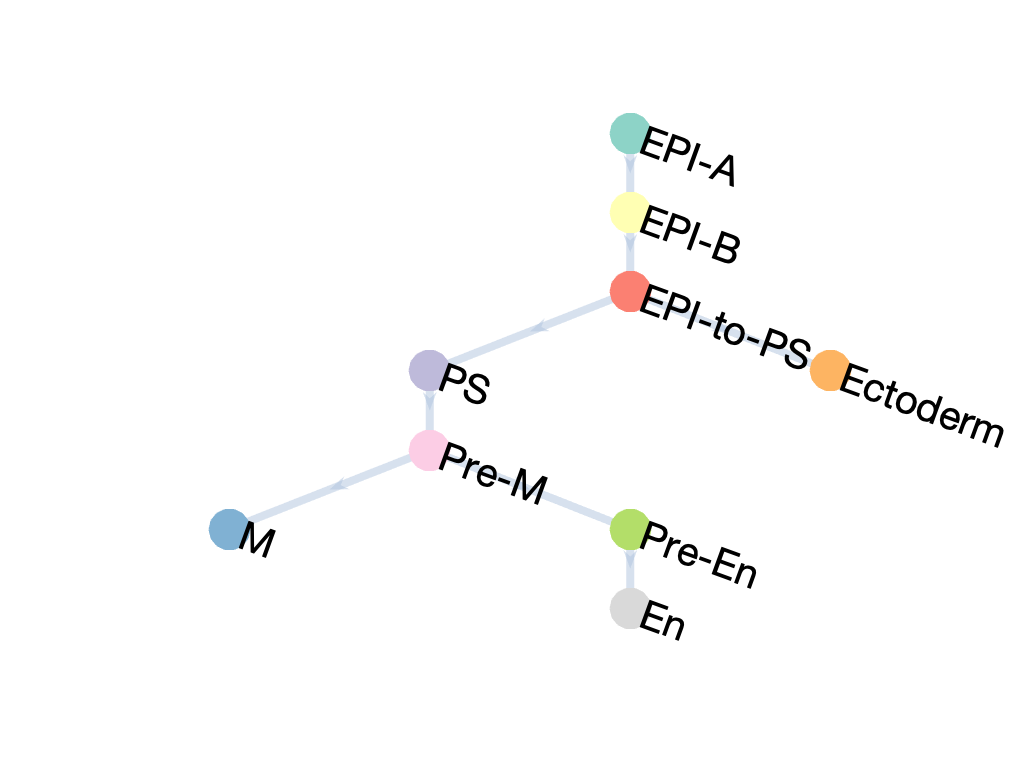

InferLineage(Output, par)

To infer the MPPT (transition trajectory), we recommend to use the python package in the new version of MuTrans.

## Cell-fate Landscape Visualization

2d Projection

colors_class = brewermap(k,'set3');
P_perm = Output.P_perm;
P_rho = Output.P_rho;
w = 0.5;
P_w = w*P_perm+(1-w)*P_rho;
par.dims = 5;
par.isomap_kn = 50;
score_2d = SC_forced2d (P_w,par);

Constructing neighborhood graph...
Computing shortest paths...
Constructing low-dimensional embedding...


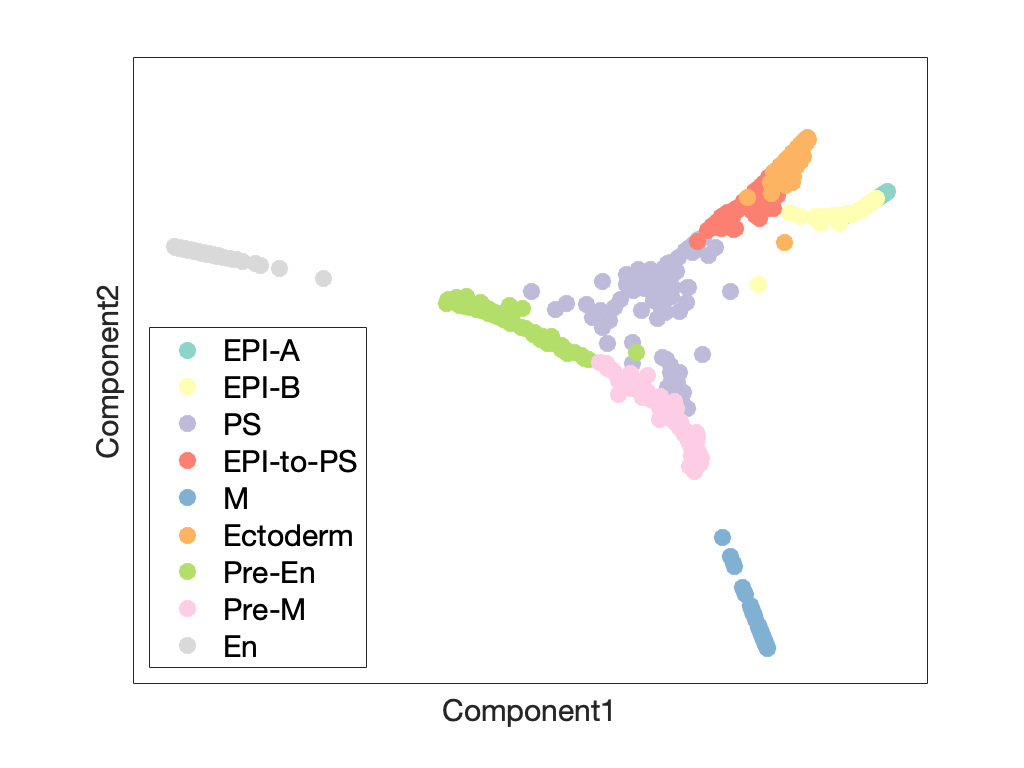

figure;
gscatter(score_2d(:,1),score_2d(:,2),class_order,colors_class,[],30);
legend({'EPI-A','EPI-B','PS','EPI-to-PS','M','Ectoderm','Pre-En','Pre-M','En'},'Fontsize',15,'Location','SouthWest')
set(gca,'xtick',[],'ytick',[]);
xlabel('Component1','Fontsize',15)
ylabel('Component2','Fontsize',15)

Output.embedding_2d = score_2d;

Landscape Construction

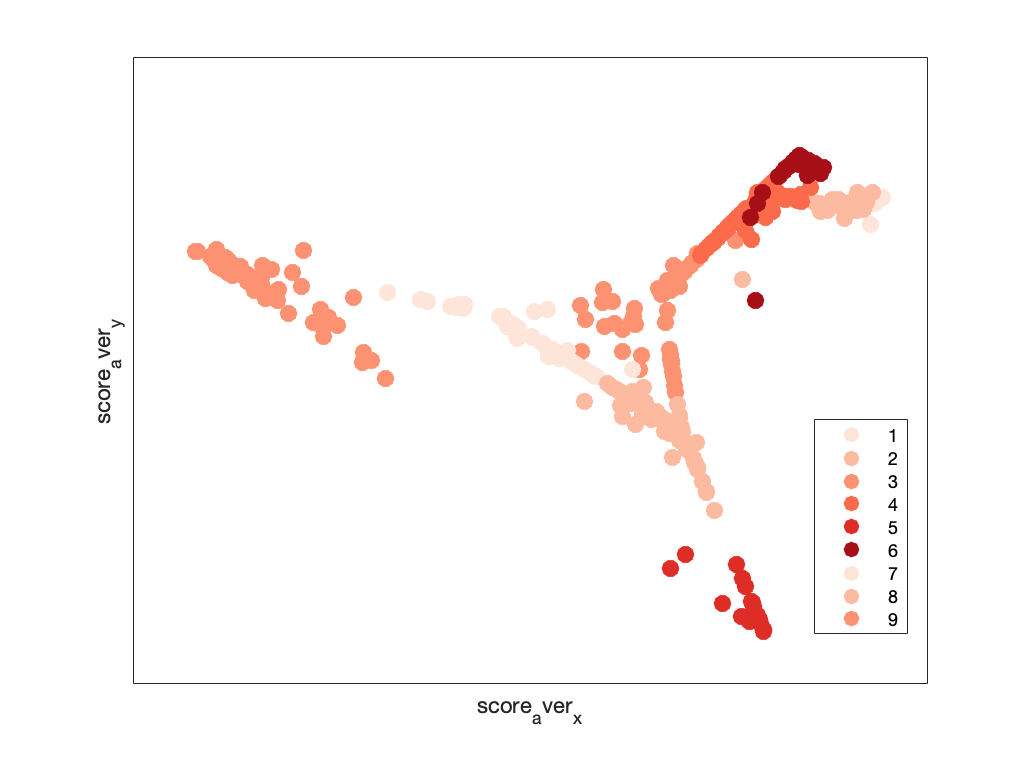

% centers
par.scaleaxis = 1;
par.mksize = 30;
labs_perm = Output.labs_perm;
par.plot_label = labs_perm;
par.legend_text = {'Day 0','Day 1','Day 1.5','Day 2','Day 2.5','Day 3'};
par.display_legend = true;
par.color_mixing = false;
par.colors = brewermap(6,'reds') ;

land = ConstructLandscape (Output, par);

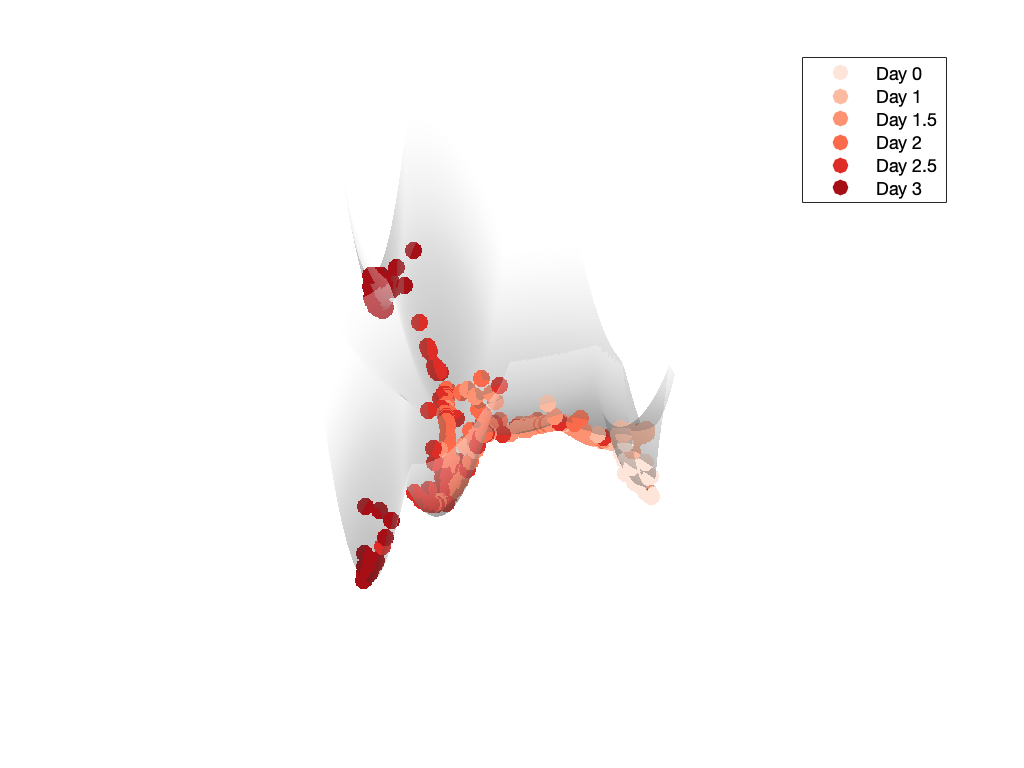

view([51 63])

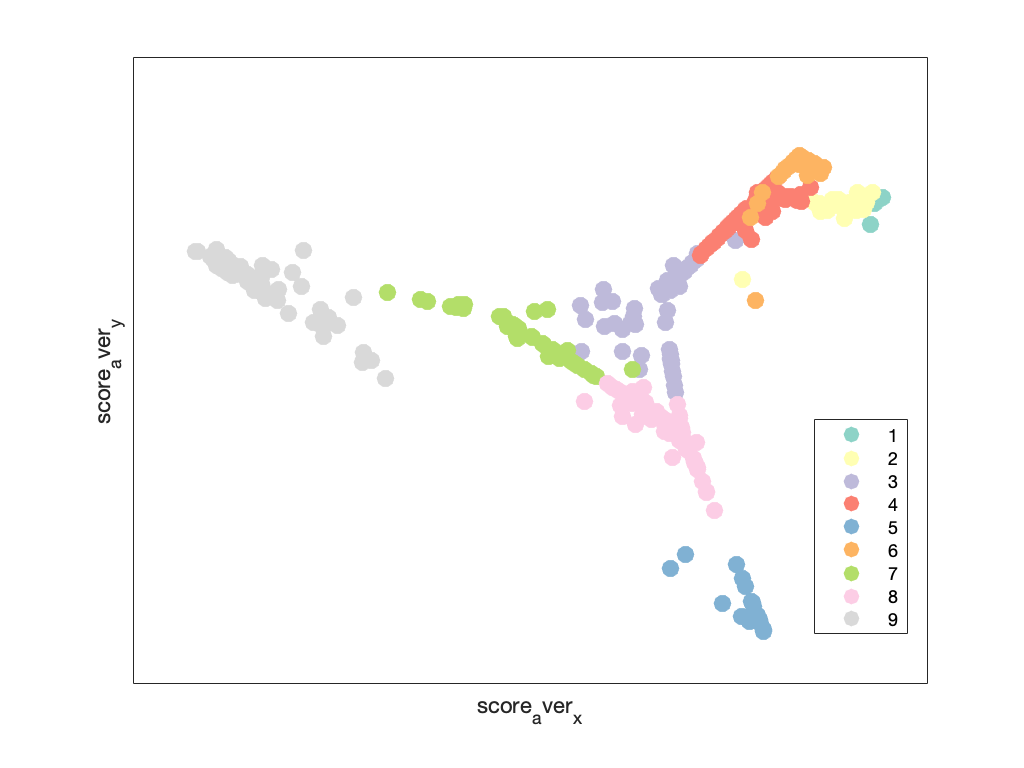

%
par.label = class_order;
par.legend_text = {'EPI-A','EPI-B','PS','EPI-to-PS','M','Ectoderm','Pre-En','Pre-M','En'};
par.display_legend = false;
par.color_mixing = true;
par.colors = colors_class ;
land = ConstructLandscape (Output, par);

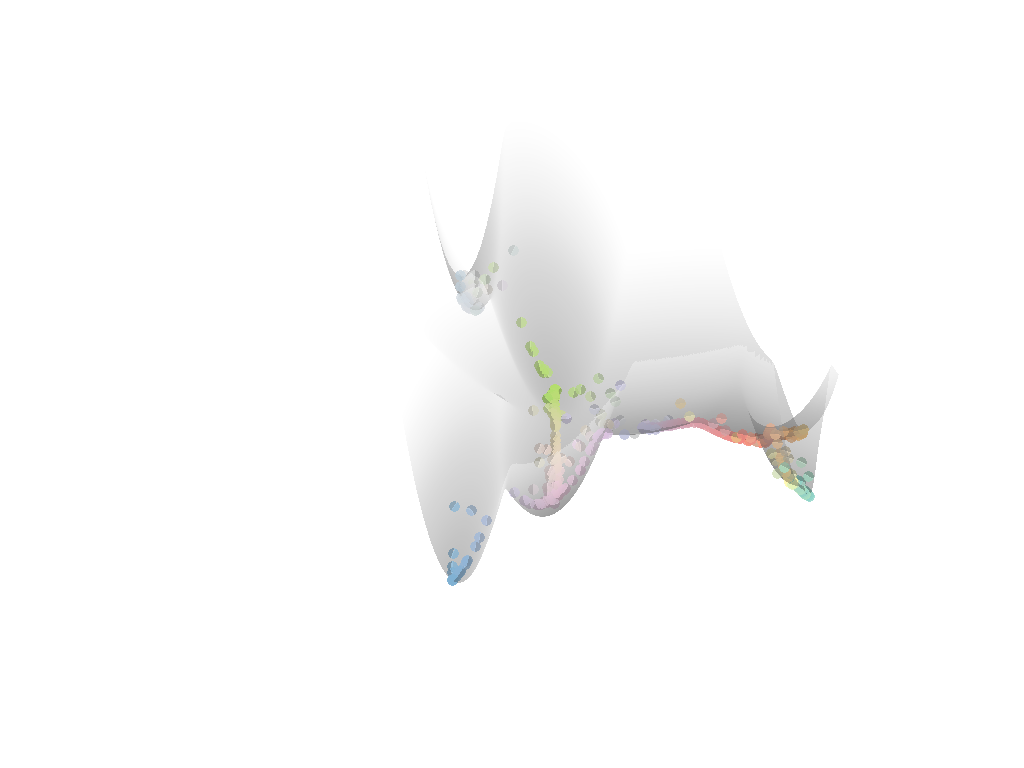

view([51 63])

## Transcendental transigion cell and gene analysis

par.display_genes_label = true;
par.display_mixing_id = true;
par.genes = genes';
par.true_labs = labs_perm;
par.thresh_de_pvalues = 5e-3;
par.thresh_ms_pvalues = 1e-2;
par.genes_label = false;
par.L_select_top_genes = 5;

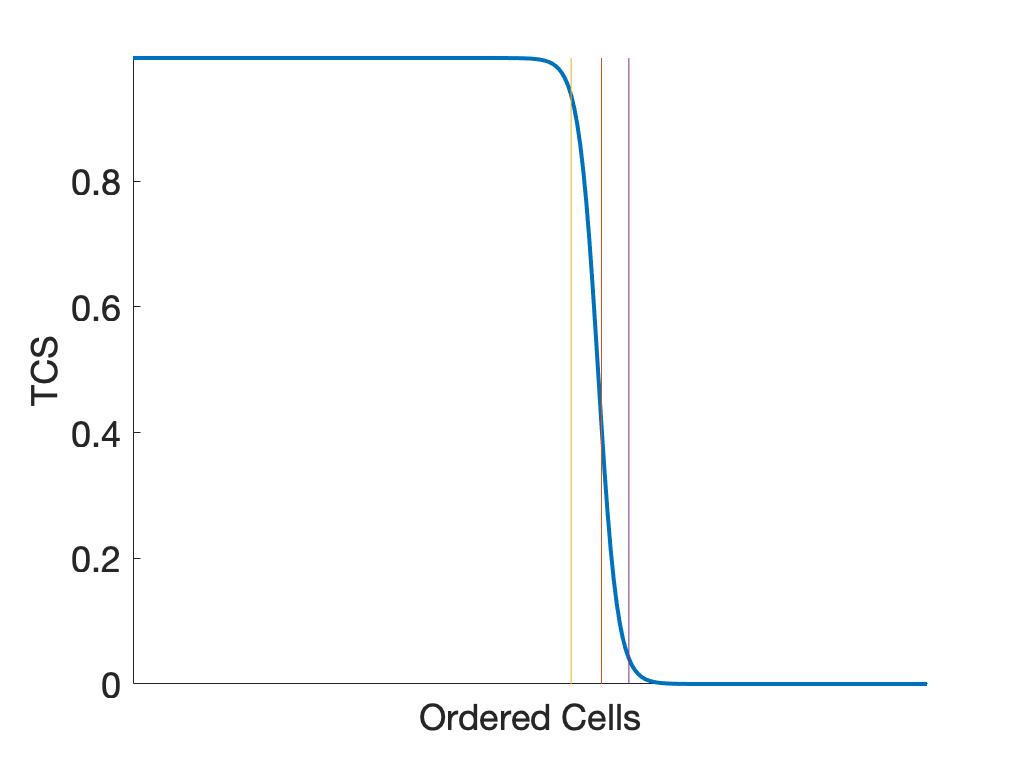

Below is the heatmap of transition genes


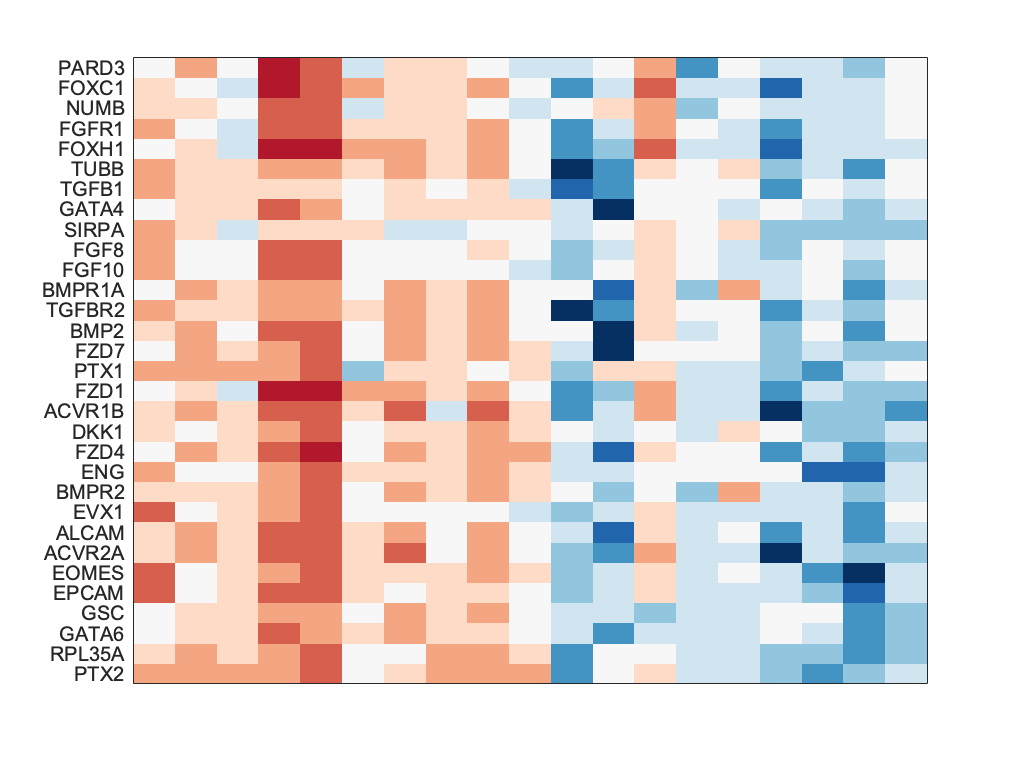

Below is the heatmap of down-regulated MS/IH genes


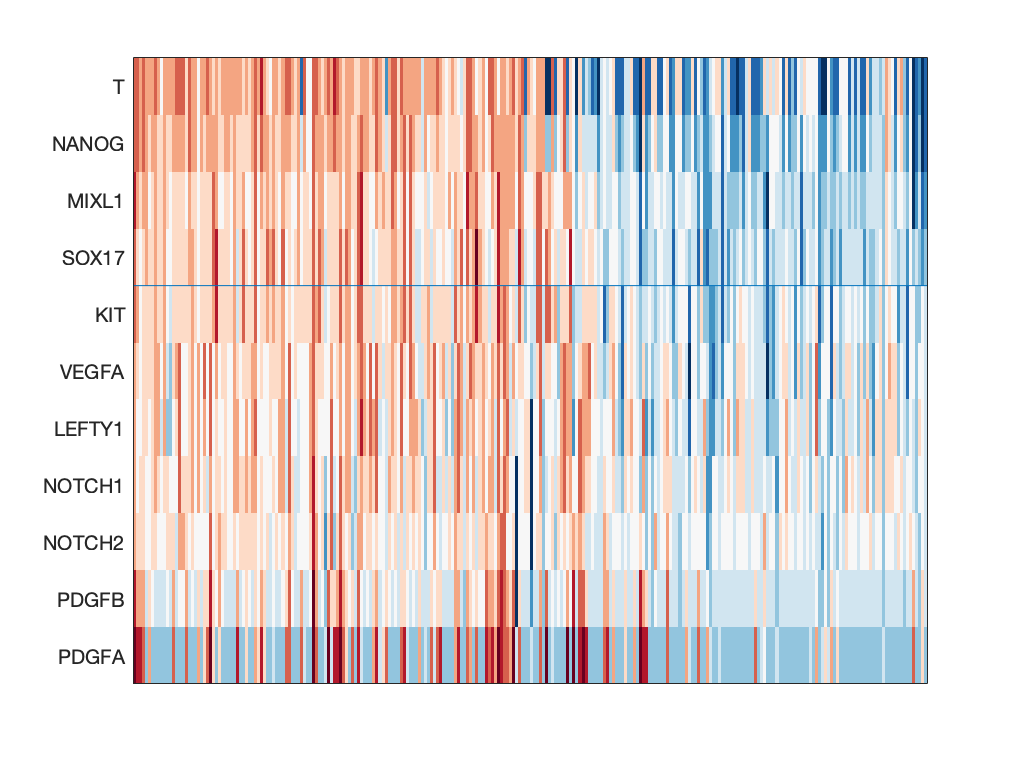

Below is the heatmap of up-regulated MS/IH genes


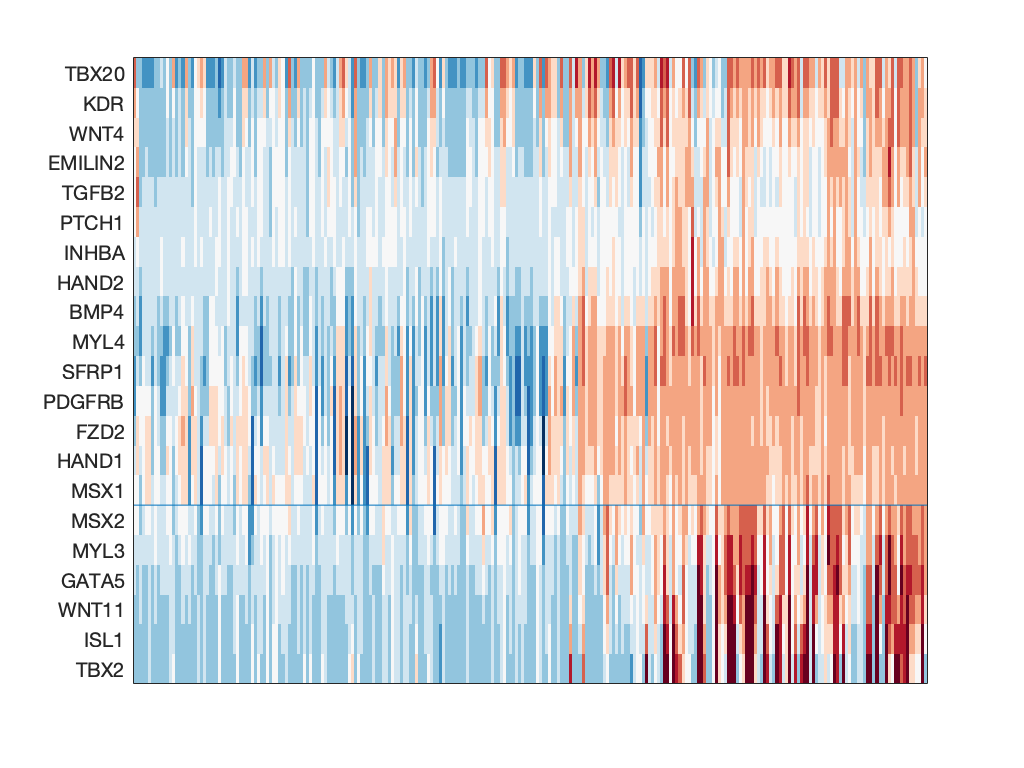

Below is the heatmap of all top genes


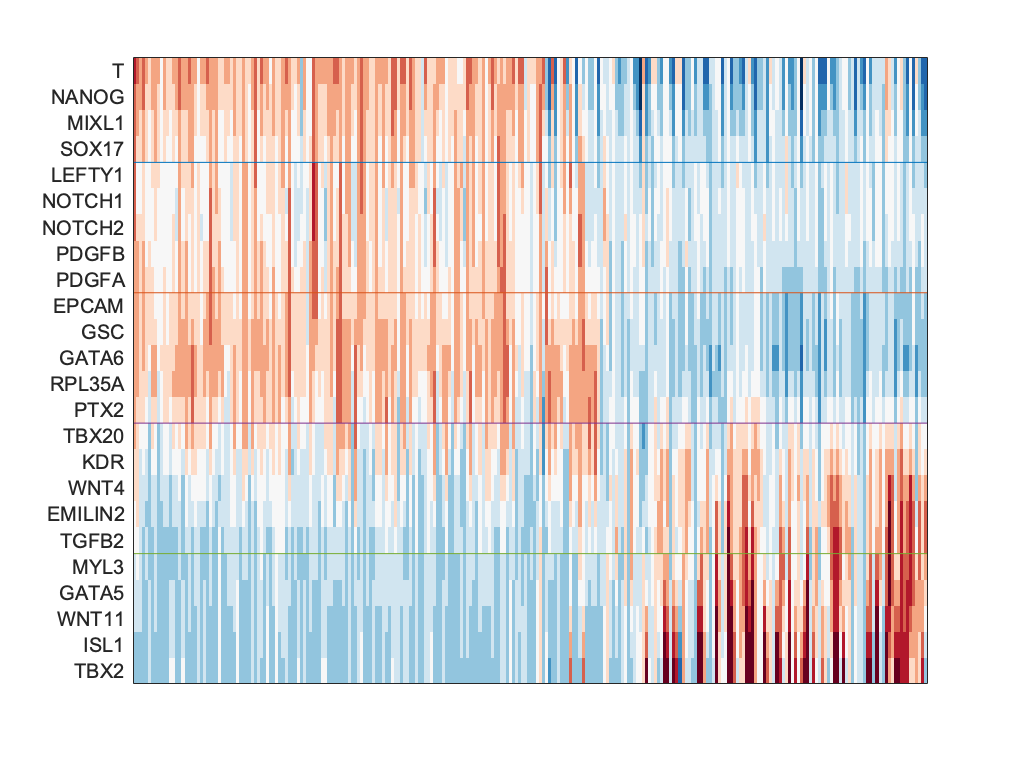

Below is the gradual cell indentity change of the interested process


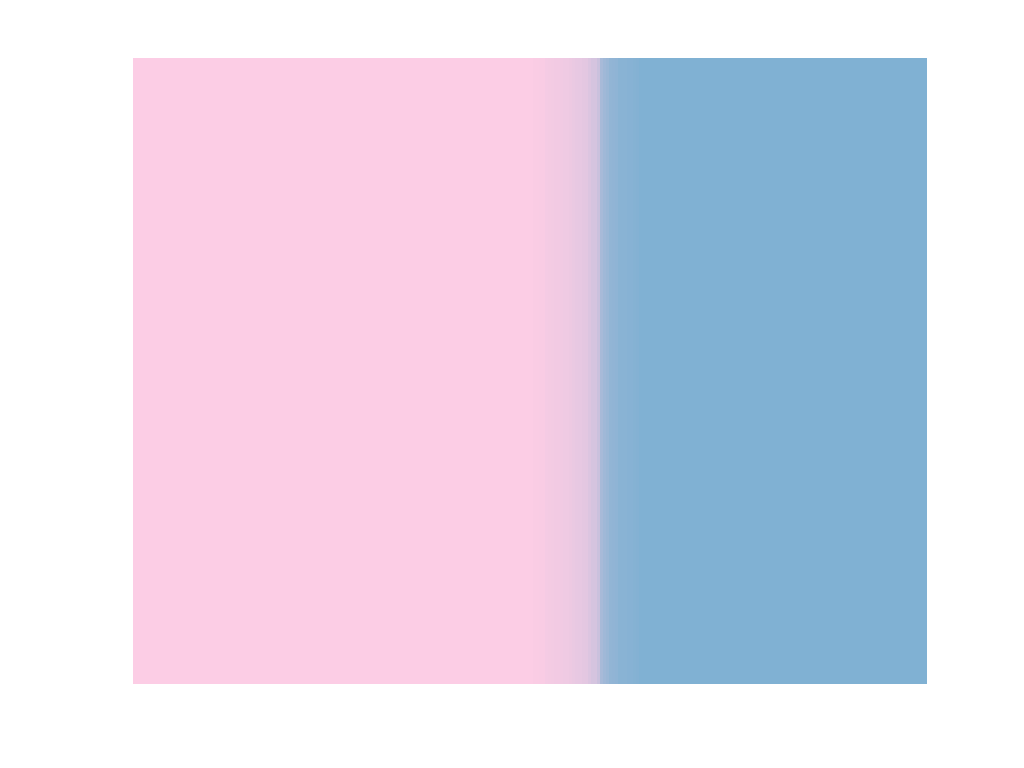

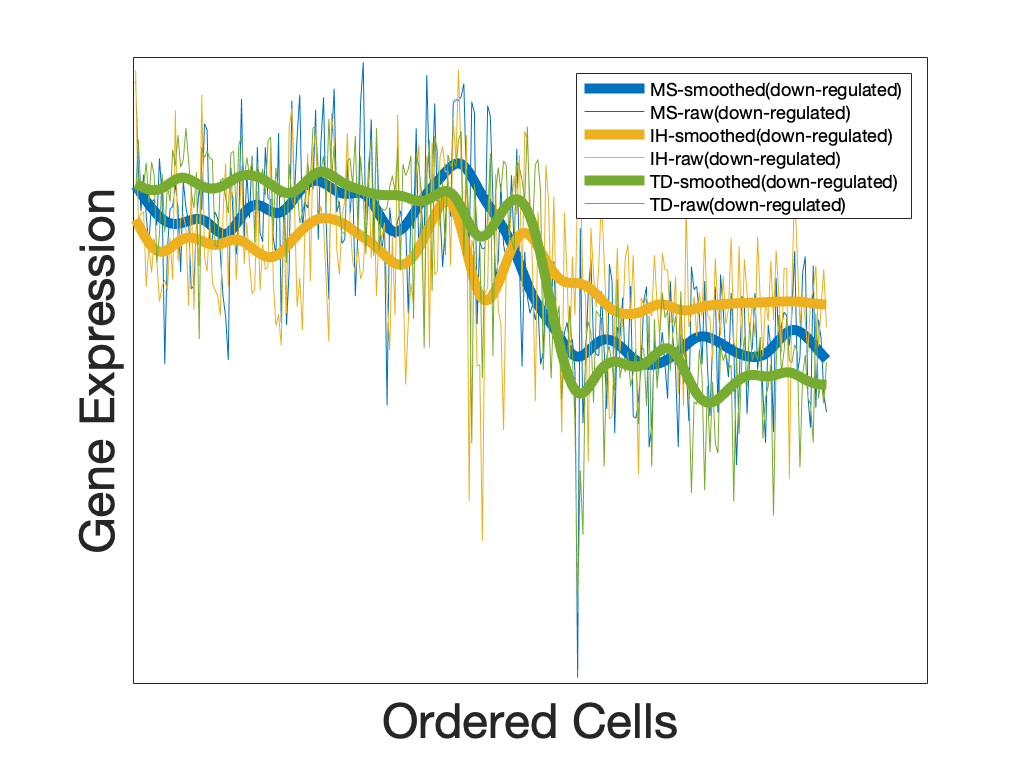

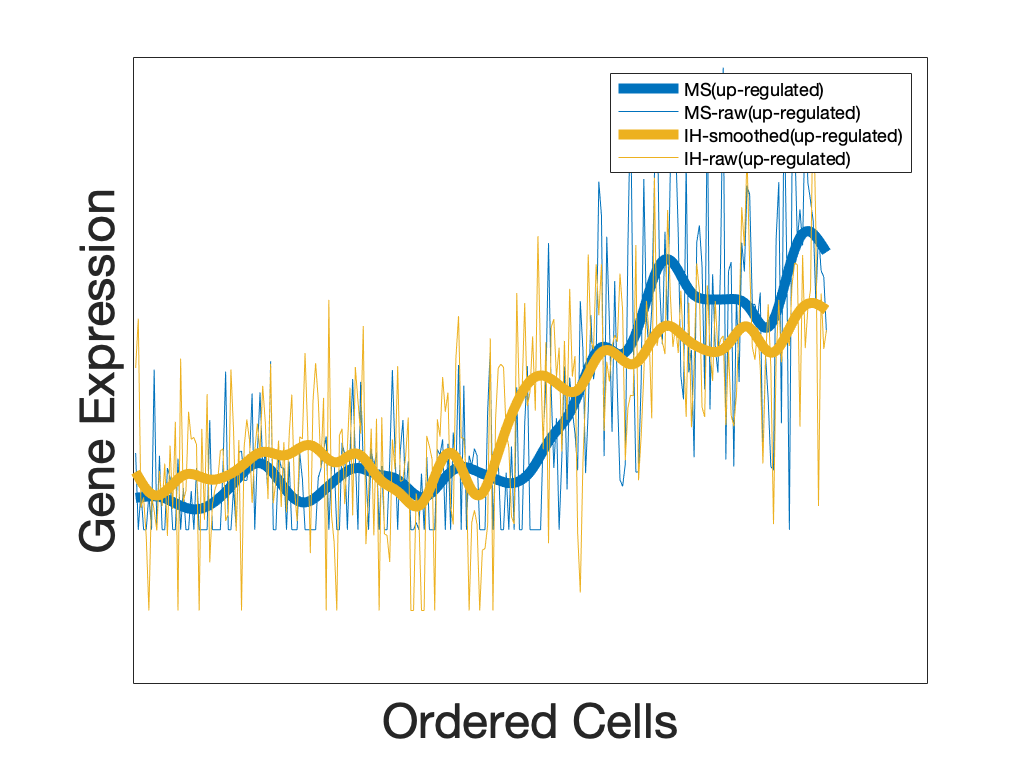

gene_out_M = GeneAnalysis(8, 5, Output, par);

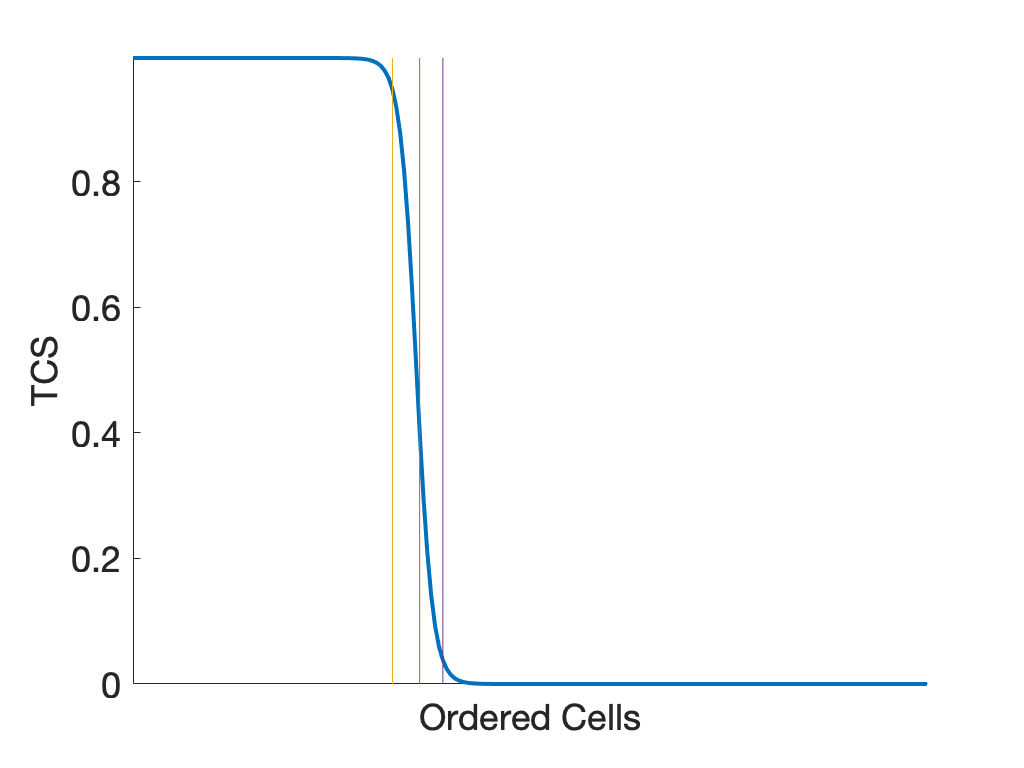

Below is the heatmap of transition genes


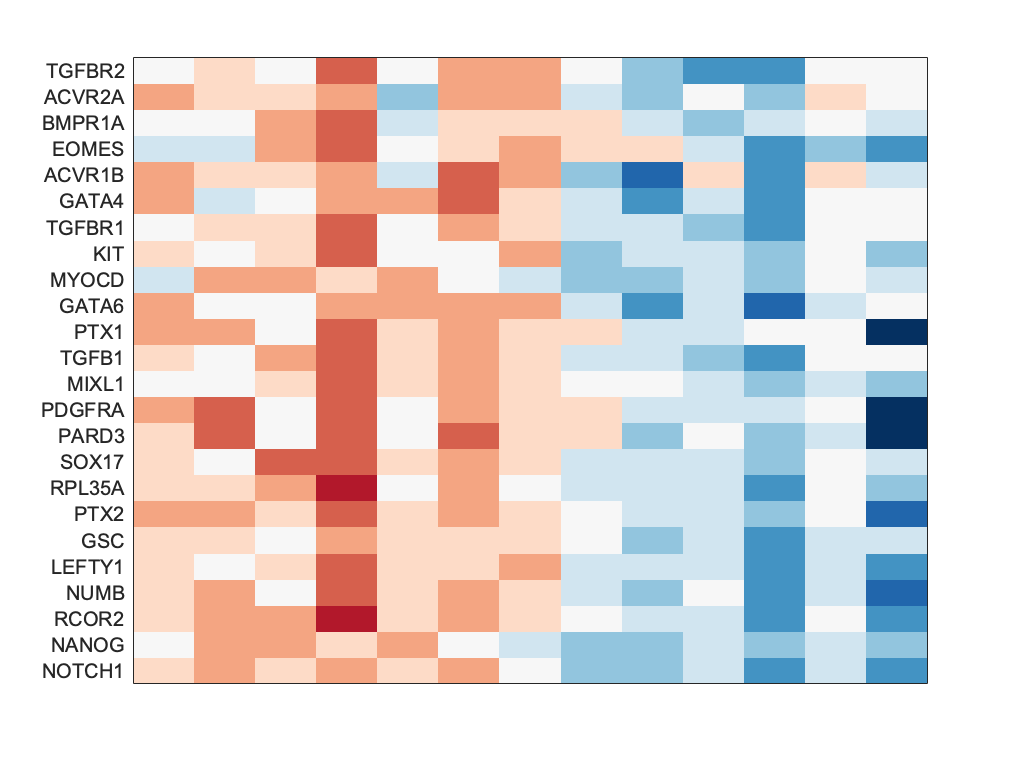

Below is the heatmap of down-regulated MS/IH genes


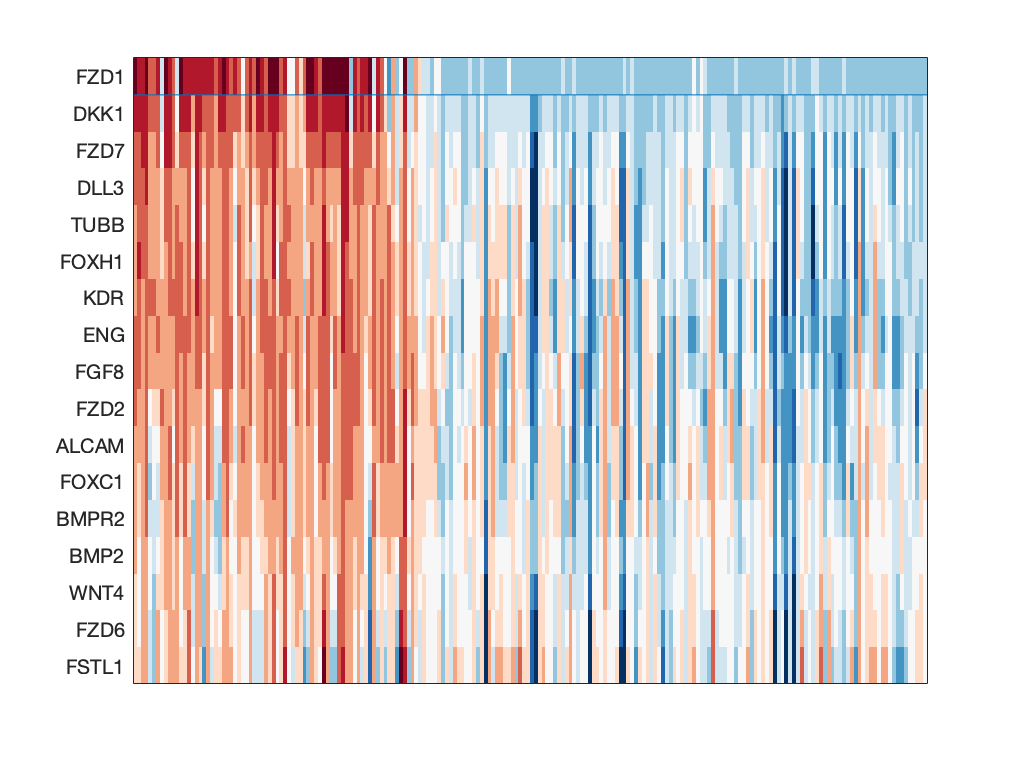

Below is the heatmap of up-regulated MS/IH genes


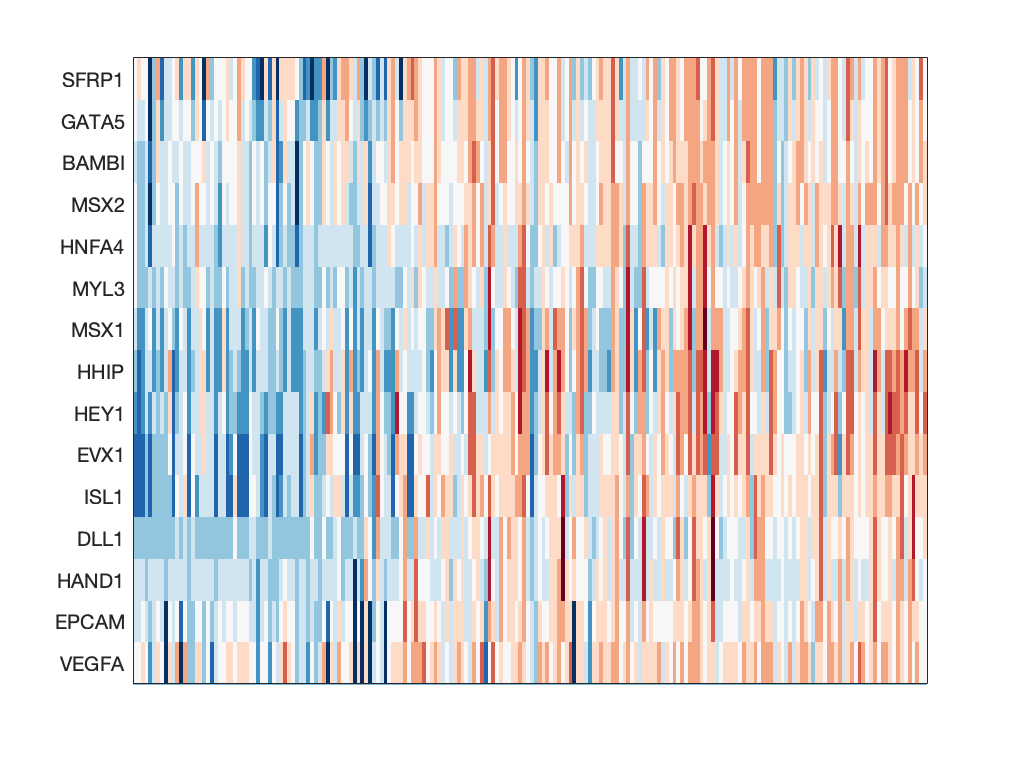

Below is the heatmap of all top genes


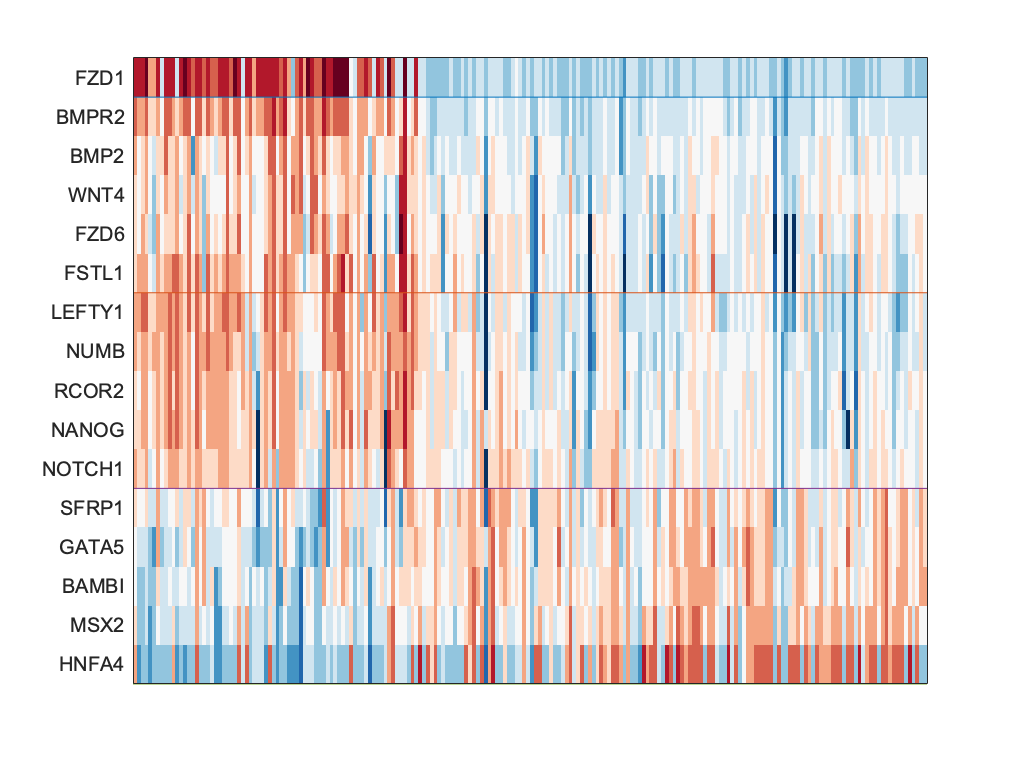

Below is the gradual cell indentity change of the interested process


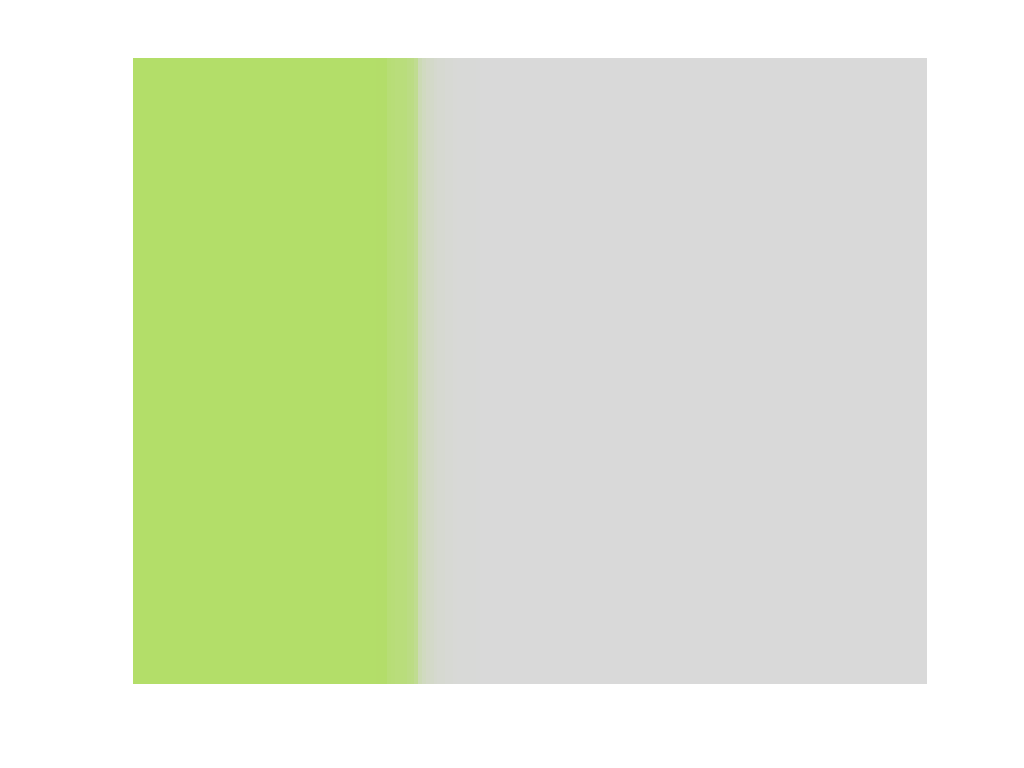

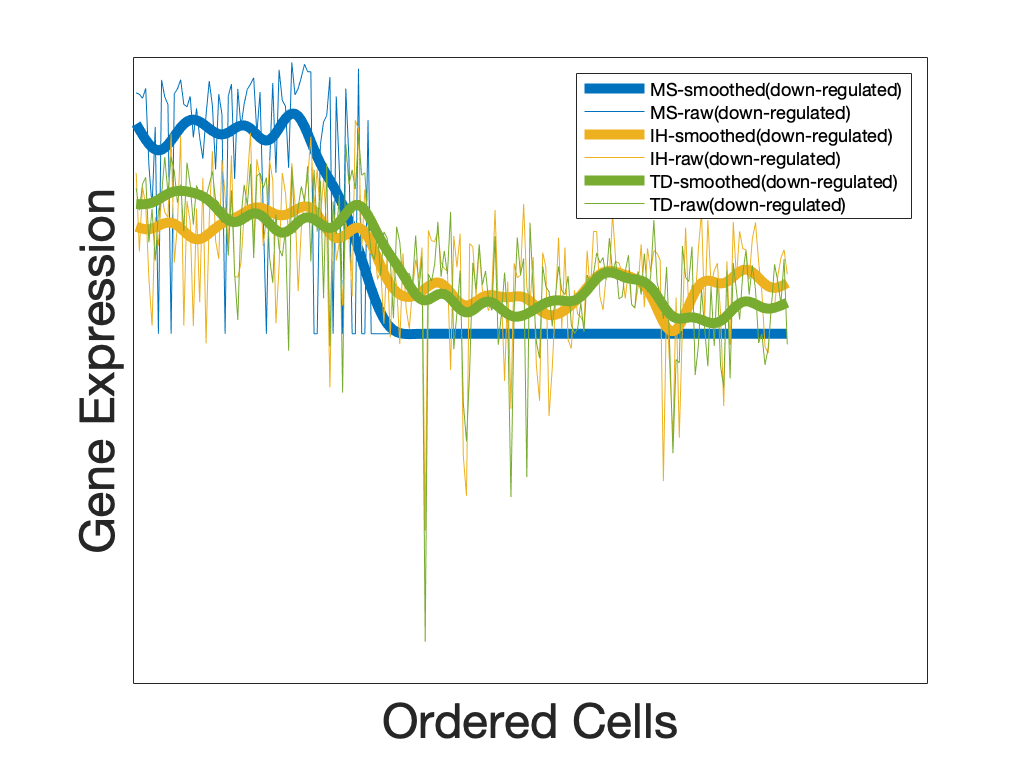

gene_out_E = GeneAnalysis(7, 9, Output, par);

Show the true labels of cells ordered by MuTrans in two bifurcation

figure;
colors_lab = brewermap(6,'reds');
imagesc(gene_out_E.cell_true_lab')
colormap(colors_lab)
axis off
set(gca,'xtick',[],'ytick',[]);
box off

figure;
colors_lab = brewermap(6,'reds');
imagesc(gene_out_M.cell_true_lab')
colormap(colors_lab)
axis off
set(gca,'xtick',[],'ytick',[]);
box off

## Additonal figures of MuTrans Output

rho_class = Output.rho_class;
perm_class = Output.perm_class;
P_hat = Output.P_hat;
P_perm = Output.P_perm;
P_rho = Output.P_rho;
P_appr_perm = Output.P_appr_perm;
mu_hat = Output.mu_hat;
k = Output.k;
H = Output.H;


max_P = 0.2* max(max(P_rho));
c_lim = [0 max_P];
cmp = 'ylgn';

figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_perm);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)
colorbar;


figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_appr_perm);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)
%colorbar;


figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_rho);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)
%colorbar;
box off


cmp = 'rdpu';
figure('rend','painters','pos',[10 10 500  400])
colormap(brewermap([],cmp))
imagesc(P_hat);
caxis([0 0.5])
axis off
set(gca,'xtick',[],'ytick',[]);
box off
colorbar;

figure;
for id_cluster  = 1:k
member(:,id_cluster) = (class_order == id_cluster)';
end
colormap(brewermap([],cmp))
imagesc(member);
caxis([0 1])
colorbar;
axis off
set(gca,'xtick',[],'ytick',[]);
box off

figure;
colormap(brewermap([],cmp))
imagesc(rho_class);
caxis([0 1])
colorbar;
axis off
set(gca,'xtick',[],'ytick',[]);
box off